#### Full System:


$$R_{growth}=  (\psi_g + \psi_d)\cdot\frac{(\eta_AA + 1)^{n_1} + \left(\frac{P_R}{\delta}\right)^{n_1}}{(\eta_B B_{ext} + 1)(\eta_AA+ 1)^{n_1}+ \left( \frac{P_R}{\delta} \right)^{n_1} } - \psi_d-\psi_C \cdot \frac{\eta_{I} I \cdot  \left(\frac{P_C}{\delta}\right)^{n_2}}{\eta_{I}I \cdot \left(\frac{P_C}{\delta}\right)^{n_2}+(\eta_AA +1)^{n_2}} $$



$$\frac{\textrm{dy}}{\textrm{dt}}=R_{\textrm{growth}\;} \cdot y\left(1-y^{\upsilon } \right)$$


#### Parameter list:

x(1) = $\psi_g$=$\delta$

x(2) = $\psi_C$

x(3) = $P_C \cdot {\left(\eta_I \cdot I\right)}^{\frac{1}{n_2 }}$

x(4) = $\psi_d$

x(5) = $\eta_B B_{\textrm{ext}}$

x(6) = $P_R$

x(7) = $n_1$

x(8) = $n_2$

#### Load data:

clear all; close all;
addpath('./MatlabFuncs/');

load('Data/Param_Fit2.mat', 'x_both'); %%mac syntax

run('./MatlabFuncs/FuncGenerator.m');

#### Set known values:

param = x_both;

% AP1903 and blasticidin concentration
B_ext0 = 50; %ug
AP0 = 20; %uM

% BLASTR and iCasp protein expression
P_R0 = param(6);
eta_I =.01 ;% assumed
P_C0 =  param(3)./((eta_I.* AP0).^(1./param(8)));

% Logistic function parameters
N_cap = 1;
Nu1 = 100 ./ (N_cap * 24); %Ncap cells secrete 100uM auxin a day 
Delta1 = log(2) / 24; %24 hour half life
A_cap = Nu1.*N_cap./Delta1;
nu = 3.14; %Correction for generalized logistic dynmaics

%enumerate varied Parameters
power_AP = logspace(0, 3, 13);
power_B = logspace(0, 3, 13);
power_R = logspace(log10(P_R0)-1, log10(P_R0)+1, 3);
power_C = logspace(log10(P_C0)-1, log10(P_C0)+1, 3);
[AP,B_ext,P_R,P_C] = ndgrid(power_AP, power_B, power_R, power_C);

#### Parameter Sweep Set up: 

%Initiate variables as symbols 
syms A positive
syms N positive

#### Symbolic Expression of rate function:

tic
parfor i = 1:numel(AP)
    % Factor in the AP1903 and Blasticidin concentration, and protein expressions into the parameters
    theta = param;
    theta(3) = param(3).* (P_C(i) ./ P_C0) .* (AP(i) ./ AP0).^(1/param(8));
    theta(5) = param(5) .* (B_ext(i) ./ B_ext0);
    theta(6) = param(6) .* (P_R(i) ./ P_R0);   
    
    rate_exp(i) = rate_comb(theta, A); 
    d_rate = diff(rate_exp(i), A);
    A_peak{i} = double(vpasolve(d_rate == 0,A,[0,A_cap]));
end  

elapsed1 = toc;
disp(elapsed1./60.*minutes) 

   2.4747 min



#### Solve for equilbrium points of rate function :

tic;
parfor i = 1:numel(AP)
    eq_ps = []
    if not(isempty(A_peak{i}))
        if double(subs(rate_exp(i),'A', A_peak{i})) * double(subs(rate_exp(i),'A',0)) < 0
            eq_ps = [eq_ps; vpasolve(rate_exp(i) == 0,A,[0, A_peak{i}],'Random',true)]; 
        end
        if double(subs(rate_exp(i),'A', A_peak{i})) * double(subs(rate_exp(i),'A',A_cap)) < 0
            eq_ps = [eq_ps; vpasolve(rate_exp(i) == 0,A,[A_peak{i}, A_cap],'Random',true)]; 
        end
    else
        if double(subs(rate_exp(i),'A', 0)) * double(subs(rate_exp(i),'A',A_cap)) < 0
            eq_ps = vpasolve(rate_exp(i) == 0,A,[0,A_cap],'Random',true);
        end
    end
    sols{i} = eq_ps
end

elapsed2 = toc;
disp(elapsed2./60.*minutes)  

   1.6205 min



#### Stabilty analysis:

%Initiate Data arrays
Pure_Death = [];
Pure_Growth = [];
mono_unstable =[];
mono_stable = [];
bi_stable = [];
bi_unstable = [];

ratebi_stable = [];
ratebi_unstable = [];
ratemono_stable = [];
ratemono_unstable = [];
ratePure_Death = [];
ratePure_Growth = [];

tic;

%Symbolic Expression for differential equation for auxin
d_A = Nu1*N - Delta1*A;
parfor i = 1:numel(AP)

    A_eq{i} = sort(unique(double(sols{i})));
   
    if isempty(A_eq{i}) 
        % Store system parameters with 0 eq. points (Pure Death)
        rate_t = double(subs(rate_exp(i),'A',20));
        
        if rate_t < 0 
            Pure_Death = [Pure_Death;[AP(i),B_ext(i),P_R(i),P_C(i)]];
            ratePure_Death = [ratePure_Death; rate_exp(i)];
            continue;
        else
            Pure_Growth = [Pure_Growth;[AP(i),B_ext(i),P_R(i),P_C(i)]];
            ratePure_Growth  = [ratePure_Growth; rate_exp(i)];
            continue;
        end
    else
    
        %Symbolic Expression for differential equation for cell population
        d_N = rate_exp(i)* N * (1 - (N / N_cap)^nu);
        
        %Construct Jacobian
        J = jacobian([d_A, d_N], [A, N]); 
        
        % Store system parameters with 1 eq. point (monophasic)
        if length(A_eq{i}) == 1 
              
            %find eigen-values at eq. point
            J_mono = subs(J, {A, N}, {A_eq{i}, Delta1.*A_eq{i}./Nu1});
            Eig_mono = double(eig(J_mono));
            
            %Evauate stability        
            if prod(real(Eig_mono) <= 0) == 0
               mono_unstable =  [mono_unstable;[AP(i),B_ext(i),P_R(i),P_C(i)]];
               ratemono_unstable = [ratemono_unstable;rate_exp(i)];
               continue;
            elseif prod(real(Eig_mono) <= 0) == 1 
               mono_stable =  [mono_stable;[AP(i),B_ext(i),P_R(i),P_C(i)]];
               ratemono_stable = [ratemono_stable;rate_exp(i)];
               continue;
            end
        end
        
        % Store system parameters with 2 eq. points (Biphasic)
        if length(A_eq{i}) == 2 
              
            %find eigen-values at eq. points
            EQ = [[0;A_eq{i}],[0;Delta1.*A_eq{i}./Nu1]]  
           
            J_bi_0 = subs(J, [A, N], [EQ(1,:)]); J_bi_mid = subs(J, [A, N], [EQ(2,:)]);J_bi_max =subs(J, [A, N], [EQ(3,:)]) ;
            Eig_bi_0= double(eig(J_bi_0)); Eig_bi_mid= double(eig(J_bi_mid)); Eig_bi_max= double(eig(J_bi_max))
           
            %Evauate stability 
            if prod(real(Eig_bi_max) <= 0)*prod(real(Eig_bi_0) <= 0) == 1 && prod(real(Eig_bi_mid) <= 0) == 0
                
                bi_stable =  [bi_stable;[AP(i),B_ext(i),P_R(i),P_C(i)]];
                ratebi_stable = [ratebi_stable;rate_exp(i)]
            else
                bi_unstable =  [bi_unstable;[AP(i),B_ext(i),P_R(i),P_C(i)]];
                ratebi_unstable = [ratebi_unstable;rate_exp(i)]
            end
        end
    end
end

total_comptime = toc; 

disp(total_comptime./60.*minutes)    

   4.4123 min



#### Make Plots:

Size = 8.5;
[k1,k2] = ndgrid(1:length(power_R) ,1:length(power_C));

parfor a = 1:numel(k1)
    
    matrix_row_PD = find(Pure_Death(:,3) == power_R(k1(a)));
    matrix_col_PD = find(Pure_Death(:,4) == power_C(k2(a)));
    index_PD = intersect(matrix_row_PD,matrix_col_PD);
    AP1903_PD{a}= Pure_Death(index_PD,1);
    BLAST_PD{a}= Pure_Death(index_PD,2);
    
    matrix_row_PG = find(Pure_Growth(:,3) == power_R(k1(a)));
    matrix_col_PG = find(Pure_Growth(:,4) == power_C(k2(a)));
    index_PG = intersect(matrix_row_PG,matrix_col_PG);
    AP1903_PG{a}= Pure_Growth(index_PG,1);
    BLAST_PG{a}= Pure_Growth(index_PG,2);
    
    matrix_row_MU = find(mono_unstable(:,3) == power_R(k1(a)));
    matrix_col_MU= find(mono_unstable(:,4) == power_C(k2(a)));
    index_MU = intersect(matrix_row_MU,matrix_col_MU);
    AP1903_MU{a}= mono_unstable(index_MU,1);
    BLAST_MU{a}= mono_unstable(index_MU,2);
    
    matrix_row_MS = find(mono_stable(:,3) == power_R(k1(a)));
    matrix_col_MS= find(mono_stable(:,4) == power_C(k2(a)));
    index_MS = intersect(matrix_row_MS,matrix_col_MS);
    AP1903_MS{a}= mono_stable(index_MS,1);
    BLAST_MS{a}= mono_stable(index_MS,2);
    
    matrix_row_BIS = find(bi_stable(:,3) == power_R(k1(a)));
    matrix_col_BIS= find(bi_stable(:,4) == power_C(k2(a)));
    index_BIS = intersect(matrix_row_BIS,matrix_col_BIS);
    AP1903_BIS{a}= bi_stable(index_BIS,1);
    BLAST_BIS{a}= bi_stable(index_BIS,2);
    
end

save("ParamMatrix_144dots_9sqrs2",'AP1903_PD','BLAST_PD','AP1903_PG','BLAST_PG','AP1903_MU','BLAST_MU','AP1903_MS','BLAST_MS',...
    'AP1903_BIS','BLAST_BIS','ratemono_unstable','ratemono_stable','ratebi_unstable','ratebi_stable','ratePure_Death','ratePure_Growth')


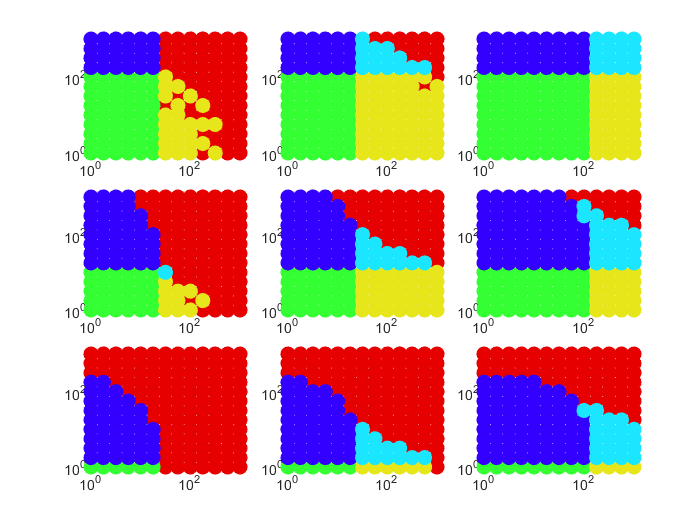

close all;
figure(1);

colorB = [.2, 0, 1];
colorG = [.2, 1, .2];
colorR = [.9, 0, 0];
colorY = [.9, .9, .1];
colorP = [.1, .9, 1];

for a = 1:numel(k1)
    subplot(3, 3, a, 'replace');
    hold on;

    plot(BLAST_PD{a},AP1903_PD{a},'o','MarkerSize',Size,'MarkerFaceColor',colorR,'MarkerEdgeColor',colorR)
    plot(BLAST_PG{a},AP1903_PG{a},'o','MarkerSize',Size,'MarkerFaceColor',colorG,'MarkerEdgeColor',colorG)   
    
    plot(BLAST_MU{a},AP1903_MU{a},'o','MarkerSize',Size,'MarkerFaceColor',colorB,'MarkerEdgeColor',colorB)    
    plot(BLAST_MS{a},AP1903_MS{a},'o','MarkerSize',Size,'MarkerFaceColor',colorY,'MarkerEdgeColor',colorY)
    
    plot(BLAST_BIS{a},AP1903_BIS{a},'o','MarkerSize',Size,'MarkerFaceColor',colorP,'MarkerEdgeColor',colorP)
 
    ax = gca;
    ax.XScale = 'log';
    ax.YScale = 'log';
    
    hold off;
end

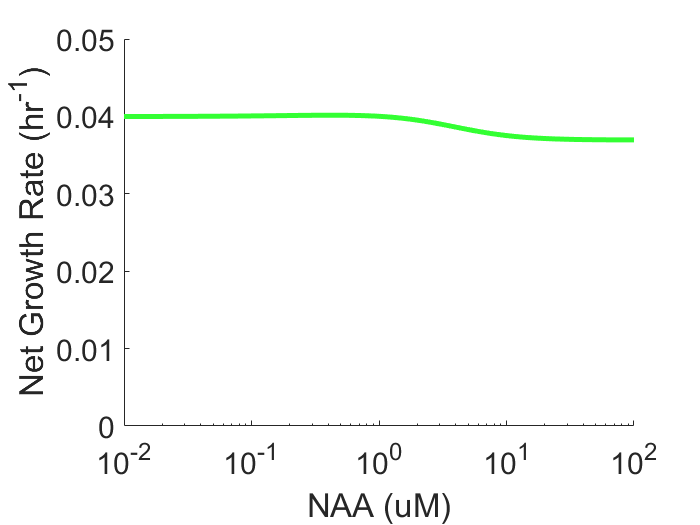

auxins = logspace(-2, 2, 100);

rVa_G = double(subs(ratePure_Growth(10),'A',auxins));

figure(2)
plot(auxins, rVa_G, 'r-', 'LineWidth', 3, 'Color', colorG);

xlabel('NAA (uM)');
ylabel({'Net Growth Rate (hr^{-1})'})

box off;

ylim([0 ,.05])
xticks([.01, .1, 1, 10, 100])
xtickformat('%.1e')

ax = gca;
ax.XScale = 'log';
ax.FontSize = 18;
ax.XAxisLocation = 'origin';

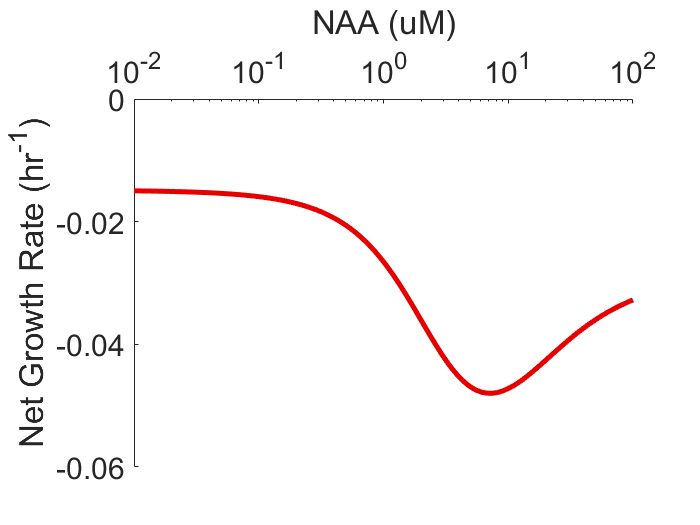

rVa_PD = double(subs(ratePure_Death(10),'A',auxins));

figure(3)
plot(auxins, rVa_PD, '-', 'LineWidth', 3, 'Color', colorR);

xlabel('NAA (uM)');
ylabel({'Net Growth Rate (hr^{-1})'})

box off;

ylim([-0.06, .0])
xticks([.01, .1, 1, 10, 100])
xtickformat('%.1e')

ax = gca;
ax.XScale = 'log';
ax.FontSize = 18;
ax.XAxisLocation = 'origin';

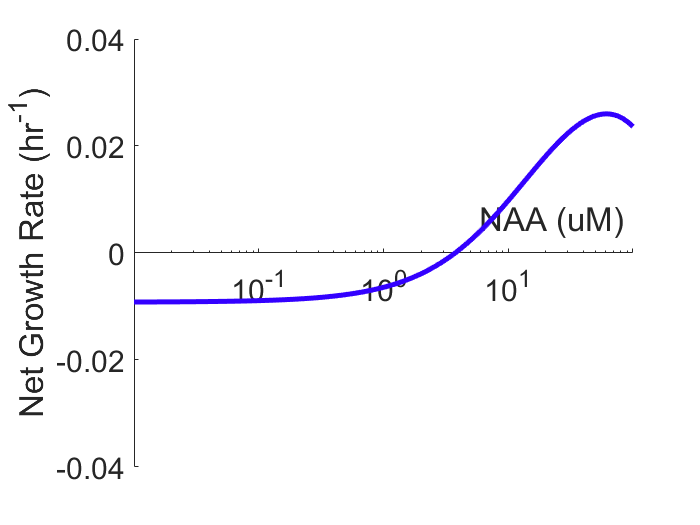

rVa_MU = double(subs(ratemono_unstable(80),'A',auxins));

figure(4)
plot(auxins, rVa_MU, '-', 'LineWidth', 3, 'Color', colorB);

xlabel('NAA (uM)');
ylabel({'Net Growth Rate (hr^{-1})'})

box off;

ylim([-0.04, .04])
xticks([.01, .1, 1, 10, 100])
xtickformat('%.1e')

ax = gca;
ax.XScale = 'log';
ax.FontSize = 18;
ax.XAxisLocation = 'origin';

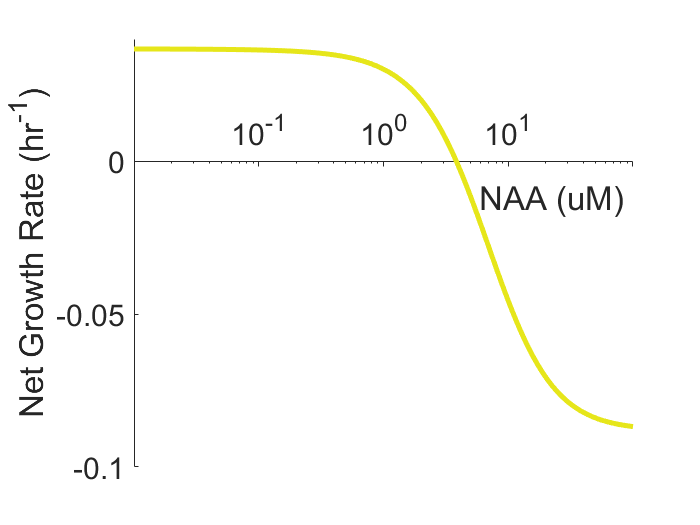

rVa_MS = double(subs(ratemono_stable(80),'A',auxins));

figure(5)
plot(auxins, rVa_MS, '-', 'LineWidth', 3, 'Color', colorY);

xlabel('NAA (uM)');
ylabel({'Net Growth Rate (hr^{-1})'})

box off;

ylim([-0.1, .04])
xticks([.01, .1, 1, 10, 100])
xtickformat('%.1e')

ax = gca;
ax.XScale = 'log';
ax.FontSize = 18;
ax.XAxisLocation = 'origin';

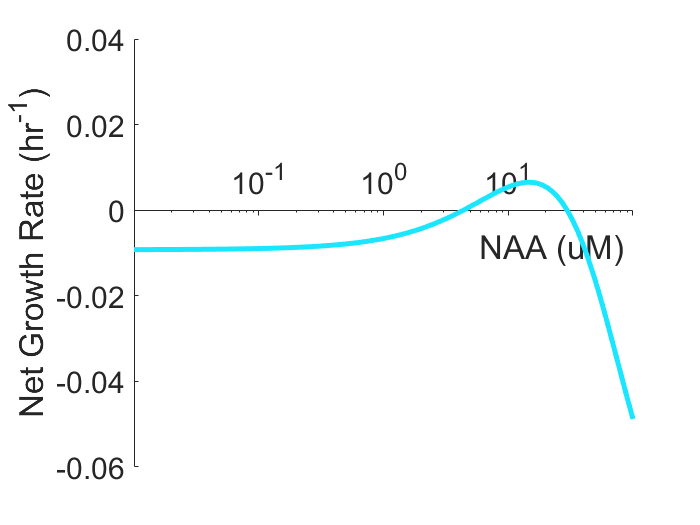

rVa_BS = double(subs(ratebi_stable(30),'A',auxins));

figure(5)
plot(auxins, rVa_BS, '-', 'LineWidth', 3, 'Color', colorP);

xlabel('NAA (uM)');
ylabel({'Net Growth Rate (hr^{-1})'})

box off;

ylim([-0.06, .04])
xticks([.01, .1, 1, 10, 100])
xtickformat('%.1e')

ax = gca;
ax.XScale = 'log';
ax.FontSize = 18;
ax.XAxisLocation = 'origin';